
supressed_print= evalc('run Term_Project_Live_Script.mlx');

clear supressed_print

sympref('FloatingPoint',true);

addpath('Clay Testing Format')

## Part Two - Improved Lyapunov Stability Arguments, and Nonlinear Variable Structure Controller 

A nonlinear control scheme is desired that can overcome the issue with the LQR approach taken above. The system will take the state from $\overset{\rightharpoonup}{x_0} ~=~(110^^\circ,0)$ to the upward operating point within five seconds. It is desired to have a final velocity of zero and a steady state angular error of less than half a degree, both being significant improvements on the original approach. The proposed law has a switchign nature, therefore it is desired to prevent chatter in the actuator at steady state - only controllers with zero continuous chatter can be considered successful. It will be considered even better to have a controller that does not dissipate energy at steady state - an almost unavoidable element of the LQR approach. Finally, the controller must be robust to model and parameter inaccuracies even in the presence of limited actuation.


$$
\begin{array}{rl}


&t_{ss} &~\leq~ &5~[sec]\\\\


&\dot{\theta}_{ss} &~=~&0 ~[\frac{deg}{s}]\\\\

&|\theta_{ss}| &~\leq~&0.5~[deg]\\\\

&v_{m,ss} &~=~&0 ~[V]


\end{array}$$


With the model utilized in this paper, the proposed controller satisfies the performance criteria and greatly improves on the steady state error and robustness of the linear quadratic regulator from part 1. The variable structure controller presented is able to take the state from $\overset{\rightharpoonup}{x_0}$ to the origin within the required time, within the margin of steady state error, and without actuation chatter or steady state power dissipation. Lyapunov stability arguments that take into account the friction nonlinearity prove that the control law is robust to model innacuracies. This is more compelling than the Lyapunov stability arguments that utilized Lyapunov's indirect method and ignored the stiction. The arguments also provide reasonable certainty that, given the choice of control parameters, the system's stability will not be affected by the actuation rails. 

### Expanded Lyapunov Stability 

The stability analysis in part one utilized Lyapunov's indirect method which had severe limitations. It is desired to utilize a Lyapunov-stability-based control technique that holds for a much larger region of the state space. A control law that is guaranteed to make the desired equilibrium point attractive globally is the ideal scenario. It is shown that this ideal scenario is not achievable with the proposed control law given that the system is effort limited (15 V rails). Additionally, the 100Hz measurement sample rate for the system is not considered in the stability analysis. Rather, it will be compensated for with an additional control structure; a boundary layer that takes over near the switching surface. 

#### Defining Lyapunov Function $V(s)$ and Switching Surface $s(\overset{\rightharpoonup}{x}) ~=~0$ 

A Lyapunov function $V(s)$ is defined in terms of scalar $s(\overset{\rightharpoonup}{x})$ such that it is positive definite. The scalar is defined:


$$s(\overset{\rightharpoonup}{x}) ~=~ \dot{\theta} + \lambda\theta$$


syms lambda v_hat v_o v_s s s_dot eta K


s_eqn = s == theta_dot + lambda*theta; 

The equation $s(\overset{\rightharpoonup}{x}) ~=~0$ describes a surface in the state space. On this surface, a decaying linear polynomial in phase variables is realized. If scalar $V(s)$ is defined as:


$$V(s) ~=~ \frac{s^2}{2}$$


then $V(s)$ is positive definite. When $V(s)$ is minimized, the system is on the switching surface and the states will decay to zero asymptotically. On the switching surface


$$ \dot{\theta} + \lambda\theta ~=~ 0$$


and


$$\theta(t + t_{tp}) ~=~ e^{-{\lambda}(t-t_{tp})}\theta(t_{tp})$$


where $t_{tp}$ is the transport time; the time when the system reached the switching surface, and $t$ is the current time. 

#### Negative Definiteness of $\dot{V}(s)$

To prove asymptotic stability, $\dot{V}(s)$ must be negative definite. This is where the control law enters consideration. A control actuation will be selected such that, through state feedback, $\dot{V}(s)$ can be made negative definite. It is shown here that there are practical limitations to this; but an effective control law can still be designed for the real input limited system. 


$$\dot{V}(s)  ~=~ s\dot{s}(s)$$


where $\dot{s}(s)$ denotes the derivative of $s(\overset{\rightharpoonup}{x}) $ formulated explicitly in terms of $s$. The derivative cannot be formulated in this manner immediately, so for now


$$\dot{s}(\overset{\rightharpoonup}{x}, v_m) = \ddot{\theta}(\overset{\rightharpoonup}{x}, v_m)  + \lambda\dot\theta$$
 

s_dot_eqn = s_dot == theta_ddot + lambda*theta_dot;
s_dot_eqn = subs(s_dot_eqn, theta_ddot, rhs(isolate(ModPendulumEOM , theta_ddot)));

Using terms from $\ddot{\theta}$, $\dot{s}(\overset{\rightharpoonup}{x}, v_m)$ can be rewritten


$$\ddot{\theta}(\overset{\rightharpoonup}{x}, v_m) 

~ =~
\frac{L\,M\,g\,\sin \left(\theta \right)-T_{\textrm{ba}} \,\mathrm{sign}\left(\dot{\theta} \right)-\frac{K_c \,N\,\dot{\theta} }{K_m \,R_a }}{J_m \,N+J_p }

~+~ \frac{K_c \,v_m }{R_a(J_m \,N+J_p) }}

~=~

f(\overset{\rightharpoonup}{x})+ bv_m$$


theta_ddot_eqn = NL_PendulumSS(2);

where 

b = B(2);
b_n = double(subs(subs(b, [L, M, g, J_m, J_p, N, K_m, T_ba]...
    ,[L_n, M_n, g_n, Jm, Jp, N_n, Km, T_ba_n]), K_c/R_a, KcRa));
f = rhs(theta_ddot_eqn - b*v_m);


$$f(\overset{\rightharpoonup}{x}) = \frac{L\,M\,g\,\sin \left(\theta \right)-T_{\textrm{ba}} \,\mathrm{sign}\left(\dot{\theta} \right)-\frac{K_c \,N\,\dot{\theta} }{K_m \,R_a }}{J_m \,N+J_p }$$


and 


$$b ~=~ \frac{K_c  }{R_a(J_m \,N+J_p) }}$$


hence


$$\dot{s}(\overset{\rightharpoonup}{x}, v_m)  ~=~ f(\overset{\rightharpoonup}{x})+ bv_m + \lambda\dot{\theta}$$


It is desired to eliminate explicit dependance on the state of the nonlinear system from the Lyapunov function's derivative. If $\dot{V}(s)$, which is more generally a function of the state (i.e. $\dot{V}(\overset{\rightharpoonup}{x})$), can be kept in terms of $s$ alone, then the negative definiteness can be a reasoned in a straightforward manner. To achieve this, the nonlinearities of the plant are cancelled out, and $\dot{s}$ is driven to zero, via a nullifying actuation voltage $\hat{v}$. 


$$\hat{\dot{s}} ~=~ \hat{f}(\overset{\rightharpoonup}{x})+ b\hat{v} + \lambda\dot{\theta}~=~0$$



$$

\hat{v} ~=~ -\frac{1}{b}(\hat{f}(\overset{\rightharpoonup}{x})+\lambda\dot{\theta})$$


where $\hat{f}(\overset{\rightharpoonup}{x})$ is the best estimate available of $f(\overset{\rightharpoonup}{x})$. Pluggin in the system dynamics

% Use symbolic toolbox to determine nullifying actuation v_hat
v_hat_eqn(theta_dot,theta)  = v_hat == rhs(isolate(rhs(s_dot_eqn) == 0, v_m));
simplify(subs(ModPendulumEOM, v_m, rhs(v_hat_eqn))); %Use to check that algebra was correct


$$\hat{v} =

\frac{R_a{\left(J_m \,N+J_p \right)}}{K_c } 

\,{\left( \frac{-L\,M\,g\,\sin \left(\theta \right)+T_{\textrm{ba}} \,\mathrm{sign}\left(\dot{\theta} \right)+\frac{K_c \,N\,\dot{\theta} }{K_m \,R_a }}{J_m \,N+J_p }

~- ~

\lambda \,\dot{\theta}\right)}\,$$


or, numerically

%substitute in numerical parameters to v_hat
v_hat_eqn_num(theta_dot,theta, lambda) = subs(v_hat_eqn, [L, M, g, J_m, J_p, N, K_m, T_ba]...
    ,[L_n, M_n, g_n, Jm, Jp, N_n, Km, T_ba_n]);
v_hat_eqn_num(theta_dot,theta, lambda) = subs(v_hat_eqn_num, K_c/R_a,  KcRa);



$$\hat{v} =0.3501\,\dot{\theta} +1.0684\,\mathrm{sign}\left(\dot{\theta} \right)-0.6600\,\sin \left(\theta \right)-0.1144\,\lambda \,\dot{\theta}$$


An additional actuation $v_s$, formulated as a feedback law on $s$,  is added to $\hat{v}$ to give the total control actuation $v_m$.


$$v_m ~=~ \hat{v} + v_s(s)$$


Using this input, $\dot{s}$ is 


$$\dot{s}(\overset{\rightharpoonup}{x}, \hat{v}, s)  ~=~ f(\overset{\rightharpoonup}{x})+ b(\hat{v} + v_s(s)) + \lambda\dot{\theta}$$



$$\dot{s}(\overset{\rightharpoonup}{x}, s)  ~=~ 


f(\overset{\rightharpoonup}{x})

-

\hat{f}(\overset{\rightharpoonup}{x})-\lambda\dot{\theta}

+ 


 b v_s(s)+ \lambda\dot{\theta}$$



$$\dot{s}(\overset{\rightharpoonup}{x}, s)  ~=~ 


F(\overset{\rightharpoonup}{x})

+ 

 b v_s(s)$$


**First Practical Limitation on Proof of Negative Definiteness - Model Uncertainty**

Above, $F$ represents a mismatch between the model and the real system. This is not a completely satisfactory result because $\dot{s}$ is not a function of $s$ alone. Therefore, the model uncertainty is the first limitation on a proof of negative definiteness that encorporates a feedback law on $s$. 


$$\dot{V}(\overset{\rightharpoonup}{x}, s) 

~=~


s(F(\overset{\rightharpoonup}{x})

+ 

 b v_s) ~<~ 0  $$
 

i.e. 


$$sbv_s ~<~ -sF(\overset{\rightharpoonup}{x})$$


If $v_s$ is not made large enough in magnitude, this inequality will surely fail. 

**Second Practical Limitation on Proof of Negative Definiteness - Saturated Actuation**

The second limitation comes from the voltage rails. The bounds on the actuation are  $\pm 15V$, 


$$|v_m| ~=~ |\hat{v} + v_s| \leq 15[V]$$
 

A trajectory requiring too much nullifying voltage at any point in time will saturate the actuator and $v_s$ will have additional requirements to satisfy negative definiteness. When this happens, $\hat{\dot{s}}  \neq 0$ and 


$$

\hat{v} ~=~ -\frac{1}{b}(\hat{f}(\overset{\rightharpoonup}{x})+\lambda\dot{\theta}) + \frac{1}{b} \hat{\dot{s}}$$



$$\dot{s}(\overset{\rightharpoonup}{x}, s)  ~=~ 


F(\overset{\rightharpoonup}{x})



+ \hat{\dot{s}}

+ 


 b v_s(s)

$$



$$\dot{V}(\overset{\rightharpoonup}{x}, s) 

~=~


s(F(\overset{\rightharpoonup}{x})



+ \hat{\dot{s}}

+ 


 b v_s(s)) ~<~ 0  $$
 

Where now the condition for negative definiteness is affected by the value of $\hat{\dot{s}}$. This report will not address the possibility of reducing the model uncertainty, but $\lambda$ and a switching gain $K$will be tuned manually to ensure that, for our scenario, $\hat{\dot{s}}$ is zero and $\hat{v}$ stays far enough away from $\pm 15V$. 

### Nonlinear Variable Structure Controller Design

A control law with three meta-structures is proposed. The first is a switching law for $v_s$ that keeps $s ~=~0$ attractive in the presence of model uncertainty. 


$$v_s = -\frac{K}{b}sign(s)$$


%Use symbolic toolbox to check that the switching law algebra works out
v_s_eqn = v_s == K/b*sign(lhs(s_eqn));
v_os_eqn = v_o == rhs(v_hat_eqn) - rhs(v_s_eqn);
VSC_eqn = isolate(simplify(expand(subs(ModPendulumEOM, v_m, rhs(v_os_eqn)))), theta_ddot + lambda*theta_dot);
s_dot_check = subs(VSC_eqn, theta_ddot + lambda*theta_dot, s_dot);

The second is a smoothing proportional controller on $s$ that is implemented near a boundary layer. The discrete measurements available for feedback are shown to produce chatter in the actuator and an undesirable amount of swinging about the equilibrium point. If the aggressiveness is slowed down near the switching surface, this chatter is reduced or eliminated. 


$$v_s = -C_{BL}\frac{K}{b}s$$


The combination of the first two meta-structures is implemented as a saturation control law with suitably chosen pre and post-multiplying gains. The pre-multiplying gain $C_{BL}$ will control the size of the boundary layer along with the aggressiveness of the linear control law on $s$. The post multiplying gain $\frac{K}{b}$ will control the magnitude of the switching law outside the boundary layer. 

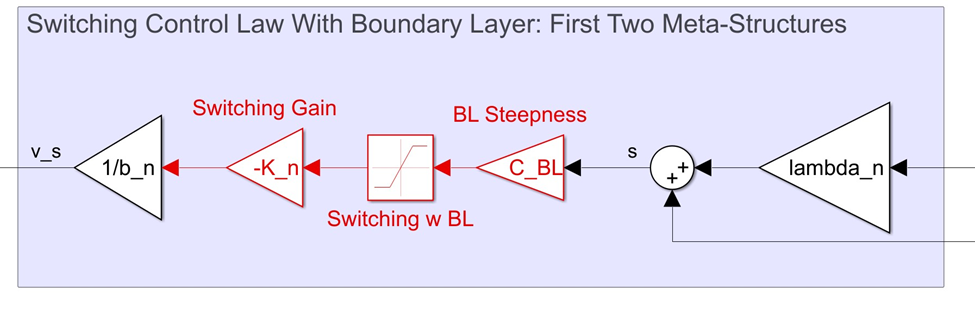

The third meta structure is a complete zeroing of the actuation if $|\theta|$ becomes suitably small. When this occurs, the static friction present in the system will take over, the actuation effort will cease, and an acceptable amount of steady state error will likely be present. Any steady state error present in the first two structures will result in actuation that only dissipates energy. If the control law evaluates to a constant voltage output at steady state and the system has reached an equilibrium with the static friction, the control effort is being dissipated as heat by the armature resistance. Additionally, if the boundary layer fails to prevent chatter, this law has a chance of preventing that. 

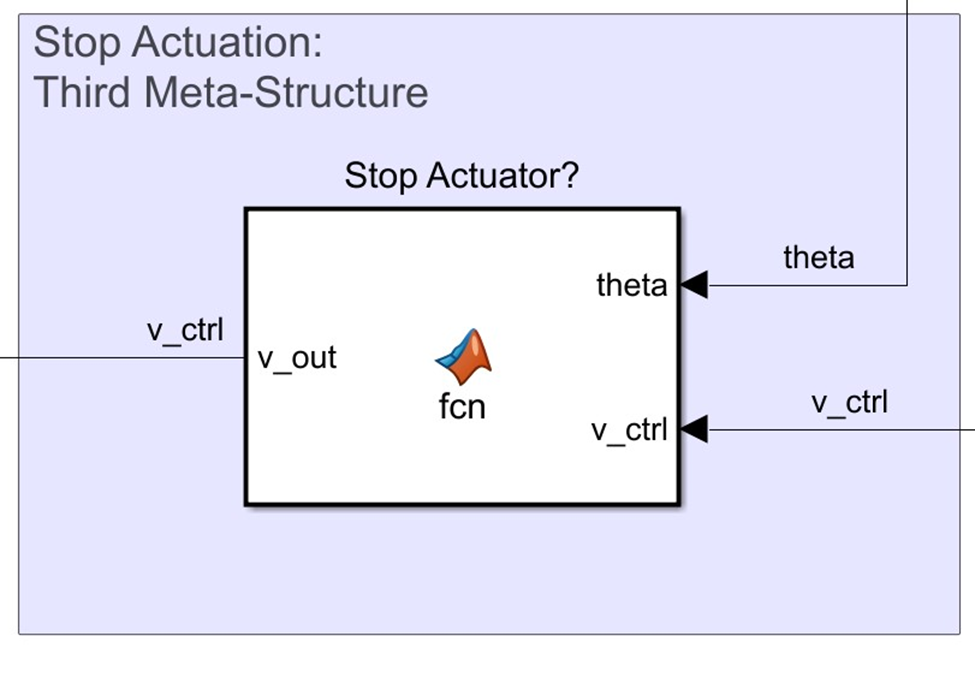

The function for this block is:

#### Switching Control Law

If the $\hat{v}$ condition is satisfied for a particular trajectory, then negative definiteness is, in part, determined by how much actuation is left over from the rails. The more of the remaining voltage $v_s$ utilizes, the more attractive the switching surface becomes. This must be balanced though, because a larger switching voltage may make the nullifying voltage exceed the design specifications. If there is always enough voltage leftover from $\hat{v}$ to combat the uncertainties, and $\frac{K}{b}$  is large enough, then the proposed signum switching law's $\dot{V}$ is negative definite for the trajectory. 


$$v_s = -\frac{K}{b}sign(s)$$



$$\dot{V}(\overset{\rightharpoonup}{x}, s) 

~=~


s(F(\overset{\rightharpoonup}{x})

-

K sign(s)) ~<~ 0  $$



$$
sK sign(s)) 

~>~ 

sF(\overset{\rightharpoonup}{x})






$$
  


$$
K|s|

~>~ 

sF(\overset{\rightharpoonup}{x})






$$
  

where 


$$|v_m| ~=~ |\hat{v} -\frac{K}{b}sign(s)| ~\leq~ 15[V]$$
 

any amount of $v_s$ that exceeds what the actuator can provide will reduce the control law's ability to combat the model uncertainties. With F = 0 however, there is no limitation on $|v_s|$ (so long as the $|\hat{v}| < 15V$ condition holds). 

#### Switching Control Law Simulation

Using $\lambda ~=~ 45$ and $\frac{K}{b} ~=~ 10$, a suitable trajectory is found from the initial conditions that keeps $\hat{v}$ within the rails. Initially, the system is simulated with a very large meaurement sample frequency of 100KHz. 

%Set initial conditions to zero velocity and theta of 110 degrees
x0 = [deg2rad(110), 0]';

fric_mod = 1; %Select 1 - couloumb friction with damping and no boundary layer
              %Select 2 - coulomb friction with damping and a smoothing boundary layer

Three_Ctrl_Struc = 2; %Set to 1 - voltage zeroing control law turned on
                      %Set to 2 - votlage zeroing control law turned off           

Switch_Law = 2;       %Set to 1 - Switching Law with Boundary Layer
                      %Set to 2 - Switching Law without Boundary Layer   
            
%Parameters
K_n = 10*b_n; 
lambda_n= 45; 
C_BL = 0; %Not necessary if the signum switching law with no boundary layer is used

tsim = 5;

t_samp = 1/100000; %Sample time for the sensors (-1) for inherited

NLout = sim('Motorized_Pendulum_VSC');



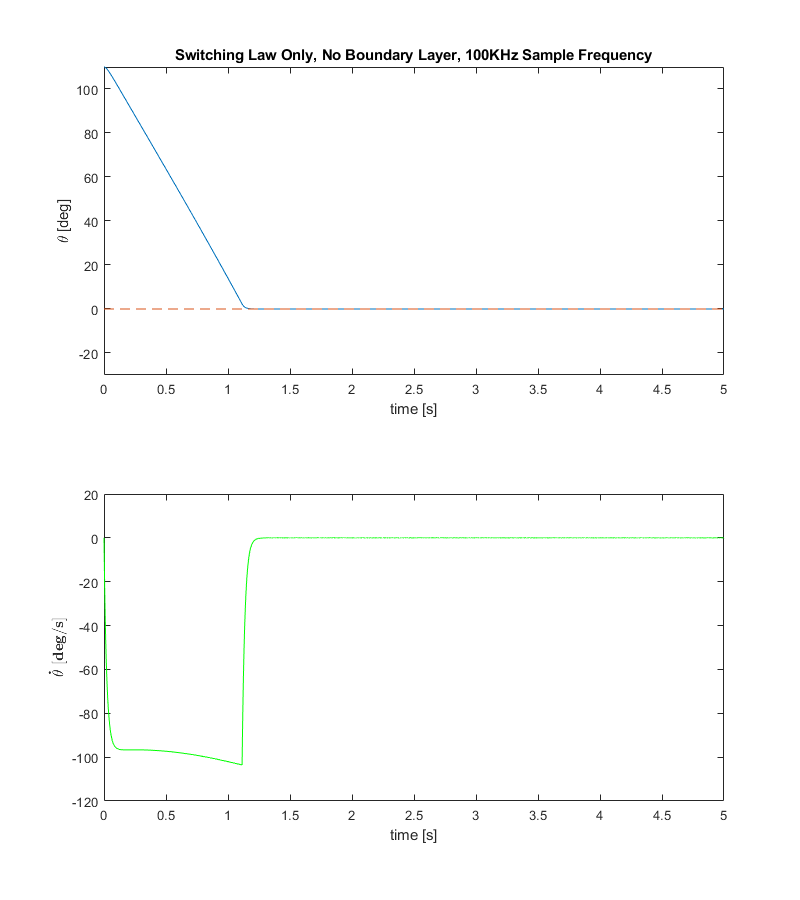

%Plot the results
figure
ax1 = subplot(2,1,1);
plot(NLout.tout,rad2deg(NLout.x(:,1)), [0 NLout.tout(end)], [0 0], '--' )
xlabel('time [s]')
ylabel('\theta [deg]')
title('Switching Law Only, No Boundary Layer, 100KHz Sample Frequency')
ylim([-30 max(rad2deg(NLout.x(:,1)))])
xlim([0 2])


ax2 = subplot(2,1,2);
plot(NLout.tout,rad2deg(NLout.x(:,2)), 'g')
xlabel('time [s]')
yl_1 = ylabel('$\bf\dot{\theta}~ [deg/s]$');
set(yl_1, 'Interpreter', 'latex');
xlim([0 2])


linkaxes([ax1,ax2],'x');
% xlim([0 5])
set(gcf,'position',[0,0,800,900]);

The performance in this simulation is excellent. This is due to the ability of the actuator to react very quickly to deviations from the switching surface. The controller reaches a $\theta$ error of about  $0.5^^{\circ}$ at around 1.15 seconds satisfying the 5 second design requirement. The $\theta$ steady state error requirement is also satisfied. 

Th_SS_Error1 = max(rad2deg(NLout.x((end-100):end,1)));
fprintf(['Steady state angular error was about ' num2str(round(Th_SS_Error1,6))...
 ' [deg] '])

Steady state angular error was about 0.000113 [deg] 

However, there is still a bit of velocity chatter occuring at 100KHz. If the switching were infinitely fast, this would not be present, but this is not realizable in simualtion or in implementation. Regardless, the system sways back and forth with a very small velocity that averages to zero. 

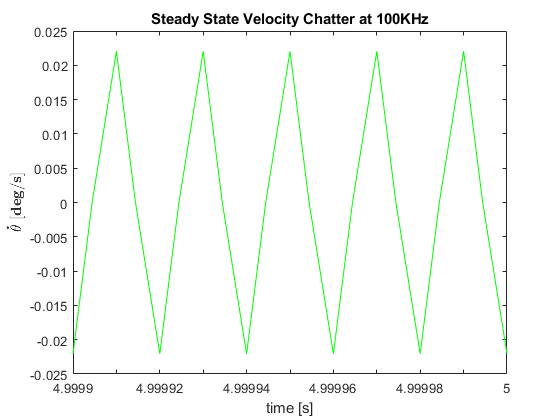

figure
plot(NLout.tout,rad2deg(NLout.x(:,2)), 'g')
xlabel('time [s]')
yl_1 = ylabel('$\bf\dot{\theta}~ [deg/s]$');
set(yl_1, 'Interpreter', 'latex');
title('Steady State Velocity Chatter at 100KHz')
xlim([4.9999 5])

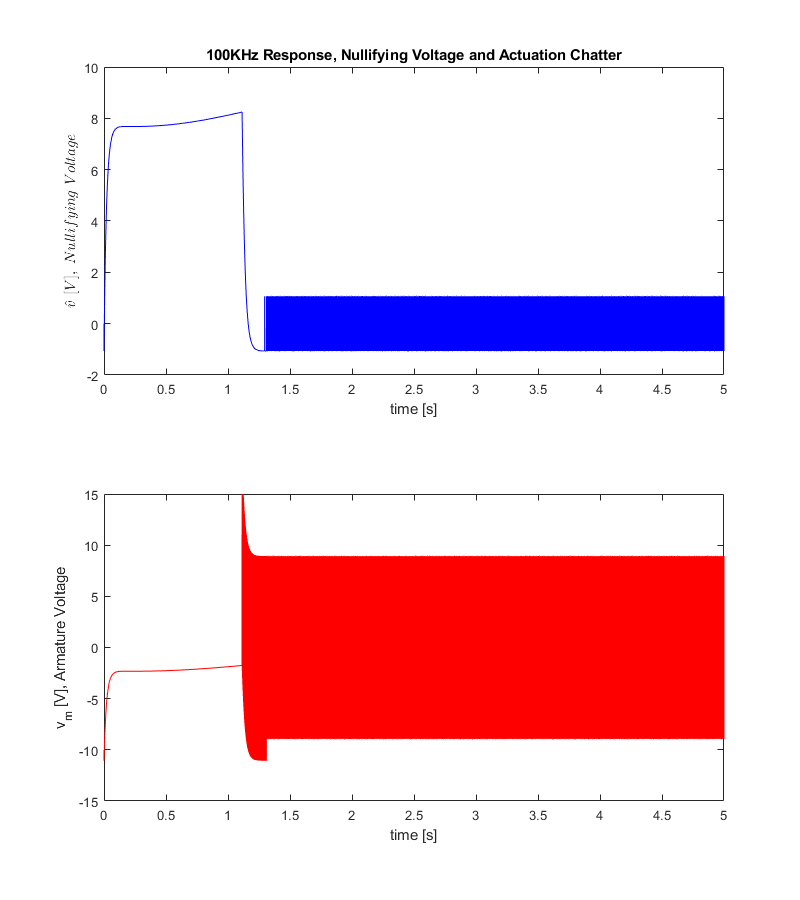

figure
ax1 = subplot(2,1,1);
plot(NLout.tout,NLout.v_hat, 'bl')
xlabel('time [s]')
yl_1 = ylabel('$ \hat{v}~ [V], ~Nullifying ~Voltage $');
set(yl_1, 'Interpreter', 'latex');
title('100KHz Response, Nullifying Voltage and Actuation Chatter')
xlim([0 2])

ax2 = subplot(2,1,2);
plot(NLout.tout,NLout.vm, 'r')
xlabel('time [s]')
ylabel('v_m [V], Armature Voltage')
xlim([0 2])

linkaxes([ax1,ax2],'x');
set(gcf,'position',[0,0,800,900]);

The nullifying voltage is shown to be within $\pm 15V$, so that design criterion is satisfied. However, a consequence of the excellent performance is that the actuation chatters rapidly. This is to be expected with a switching law, but partly motivates the addition of a boundary layer. The use of a 100KHz sample rate is not realistic - the hardware implimentation has as much slower sample rate of 100Hz. Below, this will be simulated using the same switching law that produced these initial results. 

%Set initial conditions to zero velocity and theta of 110 degrees
x0 = [deg2rad(110), 0]';

fric_mod = 1; %Select 1 - couloumb friction with damping and no boundary layer 
              %Select 2 - coulomb friction with damping and a smoothing boundary layer

Three_Ctrl_Struc = 2; %Set to 1 - voltage zeroing control law turned on
                      %Set to 2 - votlage zeroing control law turned off           

Switch_Law = 2;       %Set to 1 - Switching Law with Boundary Layer
                      %Set to 2 - Switching Law without Boundary Layer   
            
%Parameters
K_n = 10*b_n; 
lambda_n= 45; 
C_BL = 0; %Not necessary if the signum switching law with no boundary layer is used

tsim = 5;

t_samp = 1/100; %Sample time for the sensors (-1) for inherited

NLout = sim('Motorized_Pendulum_VSC');



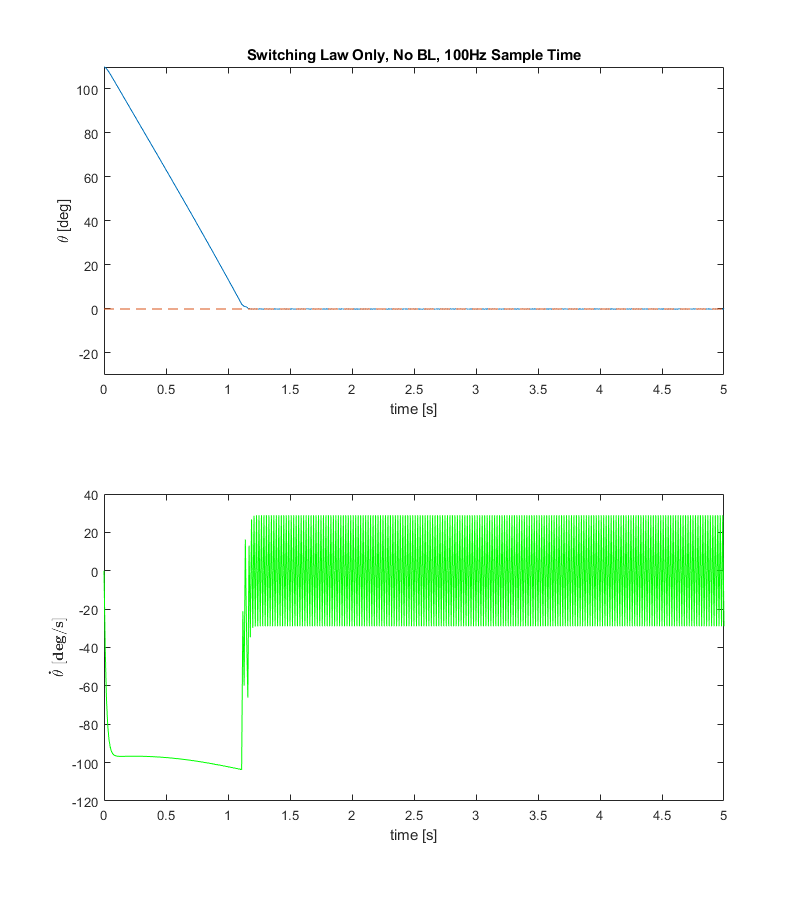

%Plot the results
figure
ax1 = subplot(2,1,1);
plot(NLout.tout,rad2deg(NLout.x(:,1)), [0 NLout.tout(end)], [0 0], '--' )
xlabel('time [s]')
ylabel('\theta [deg]')
title('Switching Law Only, No BL, 100Hz Sample Time')
ylim([-30 max(rad2deg(NLout.x(:,1)))])
xlim([0 2])


ax2 = subplot(2,1,2);
plot(NLout.tout,rad2deg(NLout.x(:,2)), 'g')
xlabel('time [s]')
yl_1 = ylabel('$\bf\dot{\theta}~ [deg/s]$');
set(yl_1, 'Interpreter', 'latex');
xlim([0 2])


linkaxes([ax1,ax2],'x');
set(gcf,'position',[0,0,800,900]);

Around the switching surface, the control law's performance is significantly degraded at 100Hz. The actuation chatter is still present as well - the nullifying voltage and armature voltage are slightly different but overall, represent the same bulk behavior as the higher frequency case. The $\lambda$ and $\frac{K}{b}$ values are still suitable for the sample rate present on the hardware. 

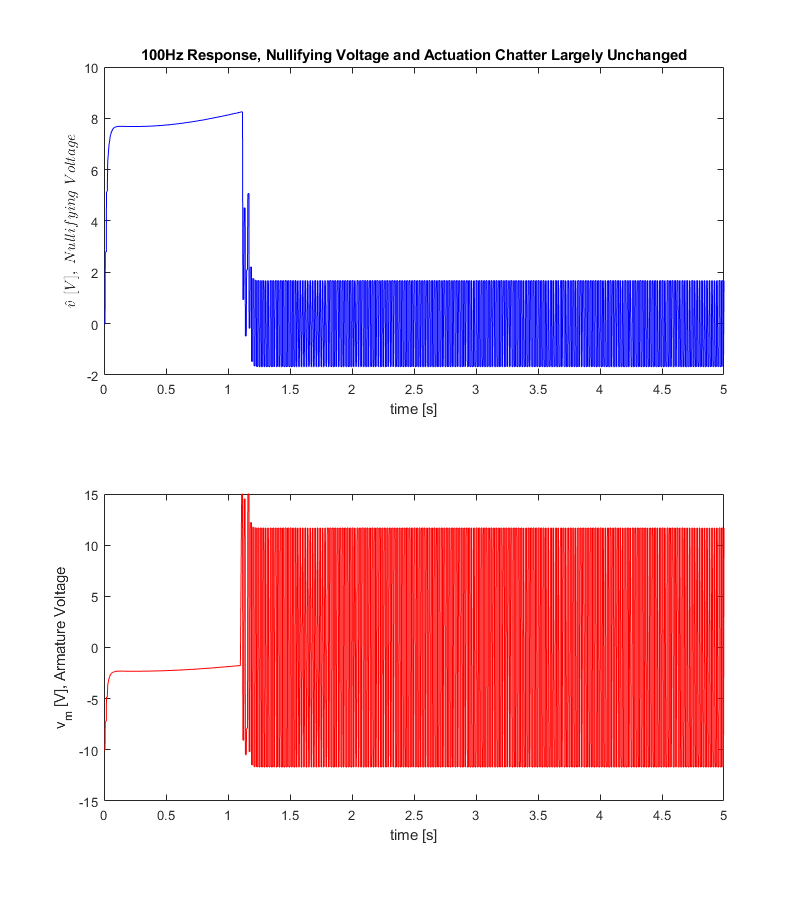


figure
ax1 = subplot(2,1,1);
plot(NLout.tout,NLout.v_hat, 'bl')
xlabel('time [s]')
yl_1 = ylabel('$ \hat{v}~ [V], ~Nullifying ~Voltage $');
set(yl_1, 'Interpreter', 'latex');
title('100Hz Response, Nullifying Voltage and Actuation Chatter Largely Unchanged')
% xlim([0 5])

ax2 = subplot(2,1,2);
plot(NLout.tout,NLout.vm, 'r')
xlabel('time [s]')
ylabel('v_m [V], Armature Voltage')
% xlim([0 5])

linkaxes([ax1,ax2],'x');
set(gcf,'position',[0,0,800,900]);

To reduce the actuation and steady state velocity chatter, a smoothing boundary layer near $s ~=~ 0$ is implemented. 

#### Smoothing Boundary Layer

Near the operating point, at $\dot{\theta}$ gets smaller and smaller, the nullfying voltage begans to be dominated by the coulomb friction term $T_{ba}sign(\dot{\theta})$. The voltage associated with this is $V_{ba} ~=~1.07V$ which is far from the rails. This will, however, be influenced by the size of the boundary layer. For a small enough boundary layer, it is of little concern how $\hat{v}$ is behaving and the design criteria can focus on two requirements:

- Keeping $v_s$ large enough in magnitude to ensure negative definiteness. 

- Smoothing out the response enough in the boundary layer to eliminate the 100Hz discretization-induced chatter.

The first design requirement is going to affect the steady state error in the presence of model uncertainty. The second requirement is about the discrete system's convergence/stability. Neither of these requirements will be approached analytically. Rather, the boundary layer steepness coefficient $C_{BL}$ will be tuned while keeping the system parameters from previous successful simulations. 

The smoothing boundary layer control law


$$v_s = -C_{BL}\frac{K}{b}s$$


 has the following negative definiteness requirement:


$$\dot{V}(\overset{\rightharpoonup}{x}, s) 

~=~


s(F(\overset{\rightharpoonup}{x})

-

C_{BL}Ks) ~<~ 0  $$



$$C_{BL}Ks^2

~>~ 

sF(\overset{\rightharpoonup}{x})






$$
  

This can be further simplified since $C_{BL}Ks^2$ is positive definite, any negative or zero value of  $sF(\overset{\rightharpoonup}{x})$ automatically satisfies the inequality. Therefore only the case where $s$ and $F(\overset{\rightharpoonup}{x})$ have the same sign needs to be considered. 


$$C_{BL}K|s|

~>~ 

|sF(\overset{\rightharpoonup}{x})|





$$
  


$$C_{BL}K

~>~ 

|F(\overset{\rightharpoonup}{x})|





$$
  

So, if $C_{BL}K$ is larger than the magnitude of the model uncertainty at every point along a boundary layer trajectory, the system will be negative definite. In the continuous case, the boundary layer, $s =0$ is attractive given this requirement. In the discrete case, however, successive actuations held constant over the sample period must produce a subsequent state that is smaller than its predecessor. A full nonlinear discretization that includes the imperfect nature of the nullifying actuation is impractical, which motivates an iterative tuning method for $C_{BL}$. It is desired to find as large a value as possible before the system loses its discrete stability. Additionally, a design factor will be added to make the boundary layer a bit larger in an attempt to prevent the system from overshooting the boundary layer completely. 

#### Switching Control Law with Boundary Layer Simulation

Using $\lambda ~=~ 45$,  $\frac{K}{b} ~=~ 10$, and $C_{BL} = 2$ a marginally suitable control response is found that eliminates velocity and actuation chatter at steady state. 

%Set initial conditions to zero velocity and theta of 110 degrees
x0 = [deg2rad(110), 0]';

fric_mod = 2; %Select 1 - couloumb friction with damping and no boundary layer
              %Select 2 - coulomb friction with damping and a smoothing boundary layer

Three_Ctrl_Struc = 2; %Set to 1 - voltage zeroing control law turned on
                      %Set to 2 - votlage zeroing control law turned off           

Switch_Law = 1;       %Set to 1 - Switching Law with Boundary Layer
                      %Set to 2 - Switching Law without Boundary Layer   
            
%Parameters
K_n = 10*b_n; 
lambda_n= 45; 
C_BL = 2; %1 worked really well with the erf friction model %2 is marginal

tsim = 5;

t_samp = 1/100; %Sample time for the sensors (-1) for inherited

NLout = sim('Motorized_Pendulum_VSC');



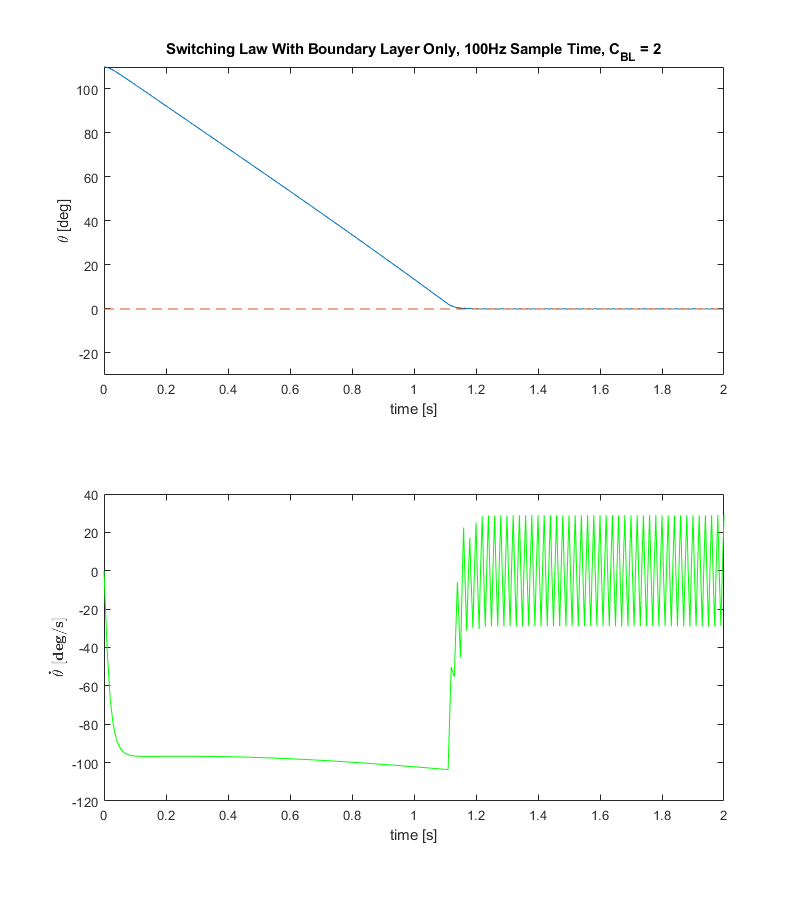

%Plot the results
figure
ax1 = subplot(2,1,1);
plot(NLout.tout,rad2deg(NLout.x(:,1)), [0 NLout.tout(end)], [0 0], '--' )
xlabel('time [s]')
ylabel('\theta [deg]')
title('Switching Law With Boundary Layer Only, 100Hz Sample Time, C_{BL} = 2')
ylim([-30 max(rad2deg(NLout.x(:,1)))])
xlim([0 2])


ax2 = subplot(2,1,2);
plot(NLout.tout,rad2deg(NLout.x(:,2)), 'g')
xlabel('time [s]')
yl_1 = ylabel('$\bf\dot{\theta}~ [deg/s]$');
set(yl_1, 'Interpreter', 'latex');
xlim([0 2])


linkaxes([ax1,ax2],'x');
set(gcf,'position',[0,0,800,900]);

There is quite a bit of oscillation around the boundary layer before the system eventually gets brought in completely. It is evident that the low sample rate is responsible for this as the velocity oscillation occurs at 100Hz. 

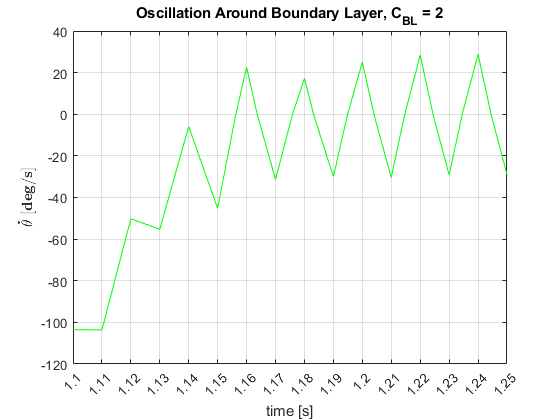

figure
plot(NLout.tout,rad2deg(NLout.x(:,2)), 'g')
xlabel('time [s]')
yl_1 = ylabel('$\bf\dot{\theta}~ [deg/s]$');
set(yl_1, 'Interpreter', 'latex');
title('Oscillation Around Boundary Layer, C_{BL} = 2')
grid('on')
xlim([1.1 1.25])
ticks = (1.1:.01:1.25);
xticks(ticks)

% xtickangle(0)


Raising the value to just 2.1 causes the system to overshoot the boundary layer and enter a state of perpetual switching. A design factor of  will be applied and a boundary layer coefficient of 1.5 will be utilized in the final control system. 

%Set initial conditions to zero velocity and theta of 110 degrees
x0 = [deg2rad(110), 0]';

fric_mod = 2; %Select 1 - couloumb friction with damping and no boundary layer
              %Select 2 - coulomb friction with damping and a smoothing boundary layer

Three_Ctrl_Struc = 2; %Set to 1 - voltage zeroing control law turned on
                      %Set to 2 - votlage zeroing control law turned off           

Switch_Law = 1;       %Set to 1 - Switching Law with Boundary Layer
                      %Set to 2 - Switching Law without Boundary Layer   
            
%Parameters
K_n = 10*b_n; 
lambda_n= 45; 
C_BL = 2.1; %1 worked really well with the erf friction model %2 is marginal

tsim = 5;

t_samp = 1/100; %Sample time for the sensors (-1) for inherited

NLout = sim('Motorized_Pendulum_VSC');



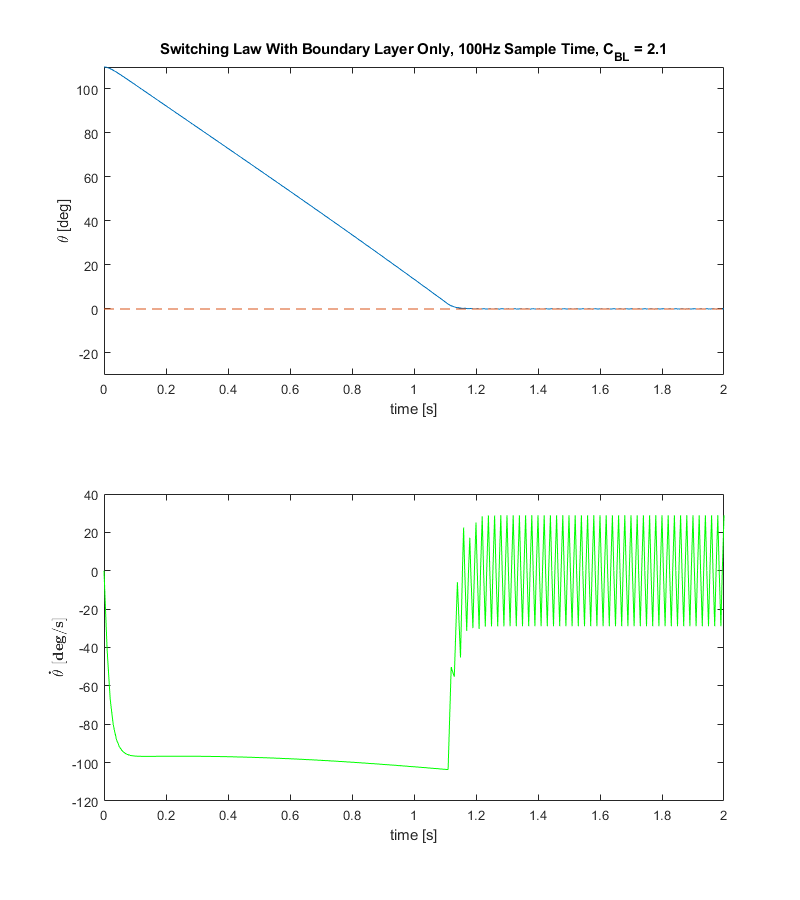

%Plot the results
figure
ax1 = subplot(2,1,1);
plot(NLout.tout,rad2deg(NLout.x(:,1)), [0 NLout.tout(end)], [0 0], '--' )
xlabel('time [s]')
ylabel('\theta [deg]')
title('Switching Law With Boundary Layer Only, 100Hz Sample Time, C_{BL} = 2.1')
ylim([-30 max(rad2deg(NLout.x(:,1)))])
xlim([0 2])


ax2 = subplot(2,1,2);
plot(NLout.tout,rad2deg(NLout.x(:,2)), 'g')
xlabel('time [s]')
yl_1 = ylabel('$\bf\dot{\theta}~ [deg/s]$');
set(yl_1, 'Interpreter', 'latex');
xlim([0 2])


linkaxes([ax1,ax2],'x');
set(gcf,'position',[0,0,800,900]);

Here, the discretization chatter has taken over and the system oscillates about the equilibrium point at 100Hz perpetually. Setting the boundary layer coefficient to 1.5 produces much better results, and will be utilized in the finalized control law. 

%Set initial conditions to zero velocity and theta of 110 degrees
x0 = [deg2rad(110), 0]';

fric_mod = 1; %Select 1 - couloumb friction with damping and no boundary layer
              %Select 2 - coulomb friction with damping and a smoothing boundary layer

Three_Ctrl_Struc = 2; %Set to 1 - voltage zeroing control law turned on
                      %Set to 2 - votlage zeroing control law turned off           

Switch_Law = 1;       %Set to 1 - Switching Law with Boundary Layer
                      %Set to 2 - Switching Law without Boundary Layer   
            
%Parameters
K_n = 10*b_n; 
lambda_n= 45; 
C_BL = 7; 

Size_BL = 3;

tsim = 5;

t_samp = 1/100; %Sample time for the sensors (-1) for inherited

NLout = sim('Motorized_Pendulum_VSC');

Simulation aborted

%Plot the results
figure
ax1 = subplot(2,1,1);
plot(NLout.tout,rad2deg(NLout.x(:,1)), [0 NLout.tout(end)], [0 0], '--' )
xlabel('time [s]')
ylabel('\theta [deg]')
title('Switching Law With Boundary Layer Only, 100Hz Sample Time, C_{BL} = 1.5')
ylim([-30 max(rad2deg(NLout.x(:,1)))])
xlim([0 5])


ax2 = subplot(2,1,2);
plot(NLout.tout,rad2deg(NLout.x(:,2)), 'g')
xlabel('time [s]')
yl_1 = ylabel('$\bf\dot{\theta}~ [deg/s]$');
set(yl_1, 'Interpreter', 'latex');
xlim([0 5])


linkaxes([ax1,ax2],'x');
set(gcf,'position',[0,0,800,900]);

This control response satisfies the steady state error requirement save for some solver anomolies that are likely attributable to the switching coulomb friction. Their frequency is greater than 100Hz and therefore cannot be attributed to the switching that occurs in the control law. The angular error was sufficiently small and the velocity was zero exactly. 

Th_SS_Error2 = max(rad2deg(NLout.x((end-10):end,1)));
Thd_SS_Error2 = max(rad2deg(NLout.x((end-10):end,2)));
fprintf(['Steady state angular error was about ' num2str(round(Th_SS_Error2,6))...
 ' [deg] and steady state angular velocity was ' num2str(round(Thd_SS_Error2,6)) ' [deg/s]'])

The actuation for this control law does not, however, satisfy the energy dissipation requirement.

figure
plot(NLout.tout,NLout.vm, 'r')
xlabel('time [s]')
ylabel('v_m [V], Armature Voltage')
title('Armature Actuation for C_{BL} = 1.5')

The system has nonzero actuation even at steady state. To combat this, the third control meta-structure is implemented below. 

#### Voltage Zeroing Law

The third meta-structure is simple and aims to eliminate power dissipation at steady state. The law allows the stiction to take over for small, allowable, steady state $\theta$ error. Getting stuck in the stiction also guarantees zero steady state $\dot{\theta}$ error. The third law will zero the voltage when $|\theta| ~\leq~ 0.001~[rad]$, or $0.057^^\circ$. If the model uncertainty is high enough, it is concievable that the system gets stuck in the boundary layer *before *this value is reached. This potentiallity will not be explored here but it is something for future consideration. The third meta structure is simulated below with the same parameters as the previous test case

%Set initial conditions to zero velocity and theta of 110 degrees
x0 = [deg2rad(110), 0]';

fric_mod = 1; %Select 1 - couloumb friction with damping and no boundary layer
              %Select 2 - coulomb friction with damping and a smoothing boundary layer

Three_Ctrl_Struc = 1; %Set to 1 - voltage zeroing control law turned on
                      %Set to 2 - votlage zeroing control law turned off           

Switch_Law = 1;       %Set to 1 - Switching Law with Boundary Layer
                      %Set to 2 - Switching Law without Boundary Layer   
            
%Parameters
K_n = 10*b_n; 
lambda_n= 45; 
C_BL = 1; %1 worked really well with the erf friction model %2 is marginal

tsim = 2;

t_samp = 1/100; %Sample time for the sensors (-1) for inherited

NLout = sim('Motorized_Pendulum_VSC');



%Plot the results
figure
ax1 = subplot(2,1,1);
plot(NLout.tout,rad2deg(NLout.x(:,1)), [0 NLout.tout(end)], [0 0], '--' )
xlabel('time [s]')
ylabel('\theta [deg]')
title('Switching Law With Boundary Layer and Voltage Zeroing')
ylim([-30 max(rad2deg(NLout.x(:,1)))])
xlim([0 tsim])


ax2 = subplot(2,1,2);
plot(NLout.tout,rad2deg(NLout.x(:,2)), 'g')
xlabel('time [s]')
yl_1 = ylabel('$\bf\dot{\theta}~ [deg/s]$');
set(yl_1, 'Interpreter', 'latex');
xlim([0 tsim])


linkaxes([ax1,ax2],'x');
set(gcf,'position',[0,0,800,900]);

This control response satisfies the steady state error requirement save for some solver anomolies that are likely attributable to the switching coulomb friction. Their frequency is greater than 100Hz and therefore cannot be attributed to the switching that occurs in the control law. The angular error was sufficiently small and the velocity was zero exactly. 

Th_SS_Error3 = max(rad2deg(NLout.x((end-10):end,1)));
Thd_SS_Error3 = max(rad2deg(NLout.x((end-10):end,2)));
fprintf(['Steady state angular error was about ' num2str(round(Th_SS_Error3,6))...
 ' [deg] and steady state angular velocity was ' num2str(round(Thd_SS_Error3,6)) ' [deg/s]'])

figure
plot(NLout.tout,NLout.vm, 'r')
xlabel('time [s]')
ylabel('v_m [V], Armature Voltage')
title('Armature Actuation for C_{BL} = 1')

### Complete Controller Implemenation

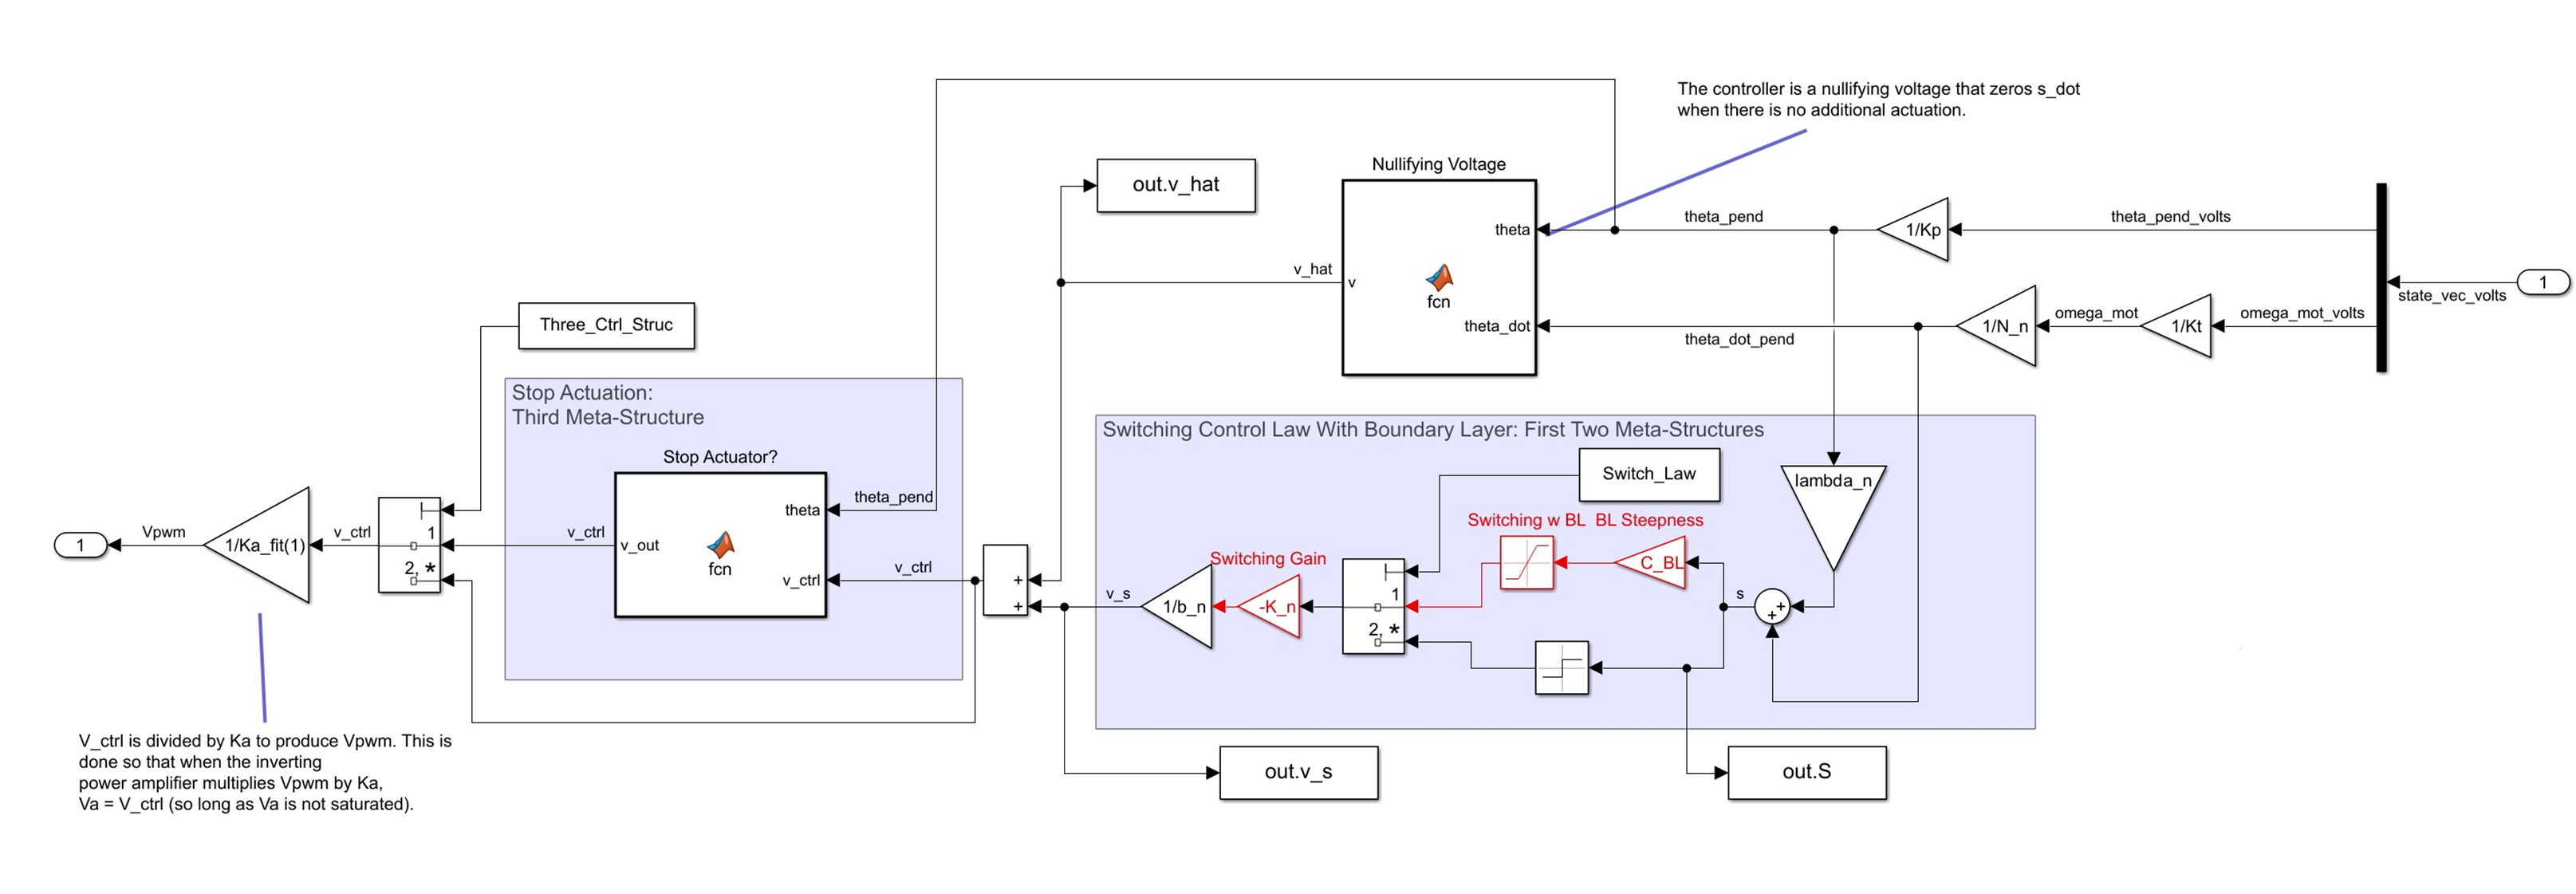

#### Summary of Control Parameters


$$
\begin{array}{rl}


&K &=~ &10~\\\\


&\lambda &=~&45 \\\\

&C_{BL} &= &1




\end{array}$$
